## SPAD Graph

### Used parameters

photon_rate = 10;  % Photons per second
dark_count_rate = 30;  % Dark counts per second
time_period = 0.1;  % Time period in seconds (100 ms)
sampling_rate = 1000;  % Sampling rate for the time axis (in Hz)

% Time axis
time = linspace(0, time_period, time_period * sampling_rate);

### Generating photon arrivals and dark counts

Assuming each count (photon or dark) generates a pulse

photon_arrivals = poissrnd(photon_rate * time_period, [1, length(time)]);
dark_counts = poissrnd(dark_count_rate * time_period, [1, length(time)]);

% Total counts
total_counts = photon_arrivals + dark_counts;

### Generating voltage output

Assuming a simple model where each count results in a spike in voltage

voltage_output = zeros(1, length(time));
for i = 1:length(time)
    if total_counts(i) > 0
        voltage_output(i) = 1;  % Setting a unit voltage spike for each count
    end
end

### Plotting the voltage output vs time

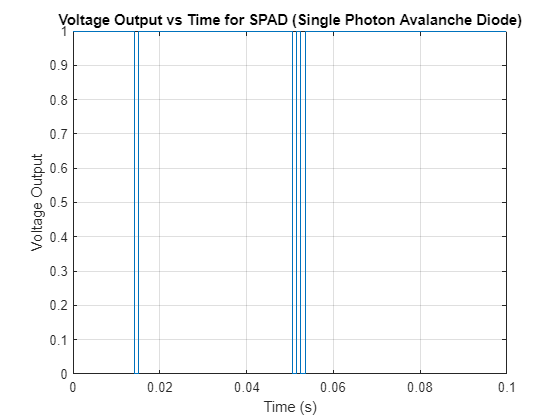

figure;
stairs(time, voltage_output);
title('Voltage Output vs Time for SPAD (Single Photon Avalanche Diode)');
xlabel('Time (s)');
ylabel('Voltage Output');
grid on;